# MA 590 : Computational Inverse Problems

# Homework 6

## Problem 1

## (a)

The function is called 'cgls.m'.

## (b)

The reconstruction of $X$ using CGLS works reasonably well but is slow. However, even if we use the maximum number of iterations of CGLS (up to $k = N-1$), we can still see a difference between the least squares approximation of $X$ and $X$ itself. Dimishing returns set in quickly - we can see running 100 iterations does not improve the approximation much beyond running 10 iterations and this pattern continues if the settings are changed to run several thousand iterations.

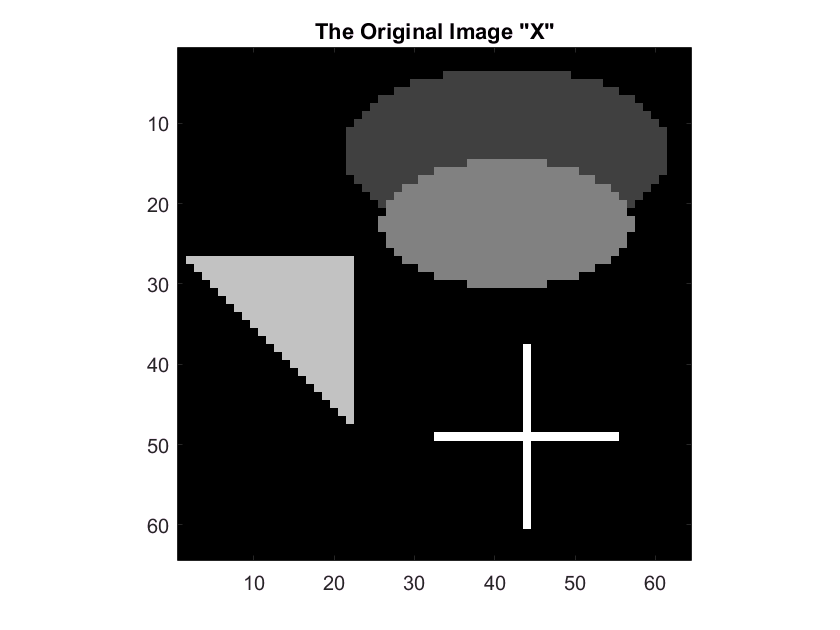

clear all
close all
clc

%Setting up Blur test problem and exploring intial results.
N = 64;
[G,y,x] = blur(N,10,1.4);

X = reshape(x,N,N);
imagesc(X)
title('The Original Image "X"')
colormap gray
axis image

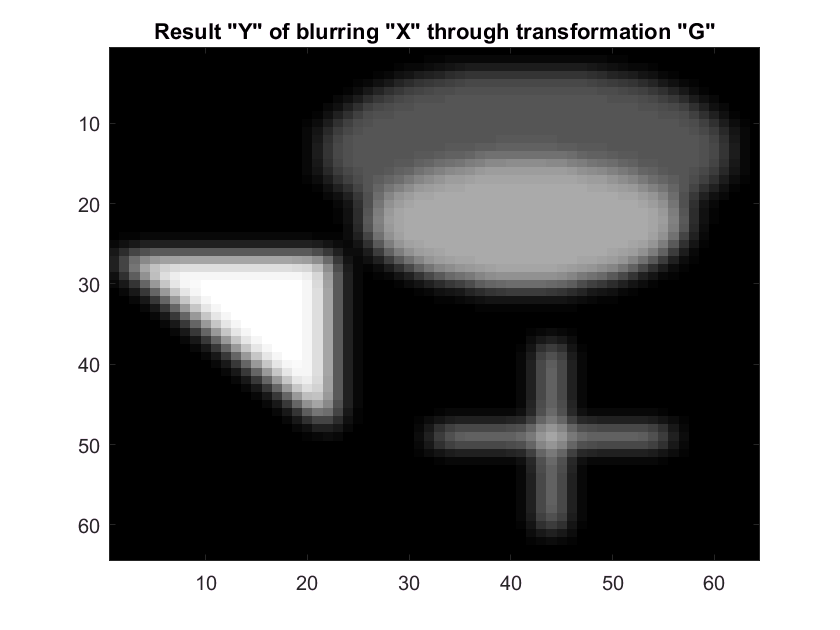


Y = reshape(y,N,N);
imagesc(Y)
title('Result "Y" of blurring "X" through transformation "G"')


tic
X_CGLS = cgls(y,G,100-1);
toc

Elapsed time is 0.446734 seconds.


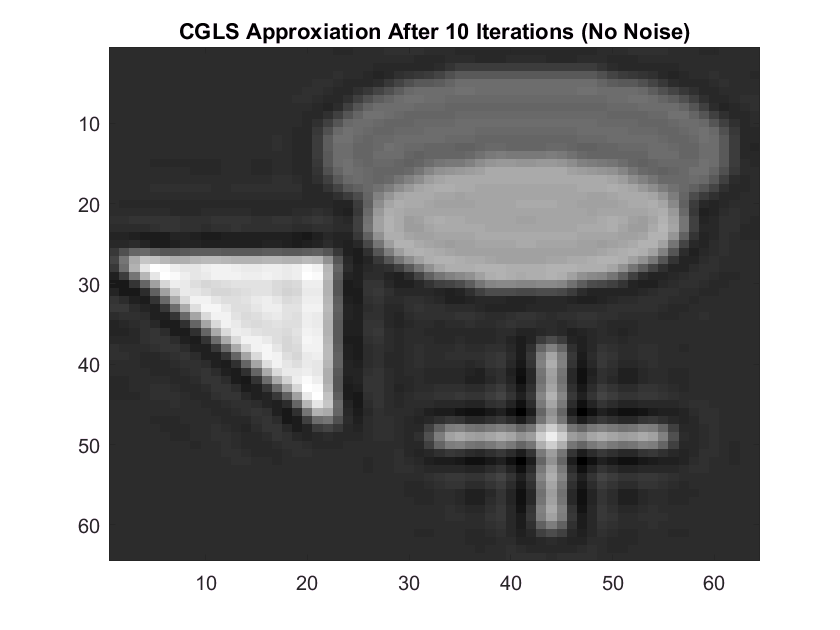


X_10 = reshape(X_CGLS(:,11),N,N);
X_50 = reshape(X_CGLS(:,51),N,N);
X_100 = reshape(X_CGLS(:,101),N,N);

%X_1000 = reshape(X_CGLS(:,1001),N,N);

imagesc(X_10)
title('CGLS Approxiation After 10 Iterations (No Noise)')

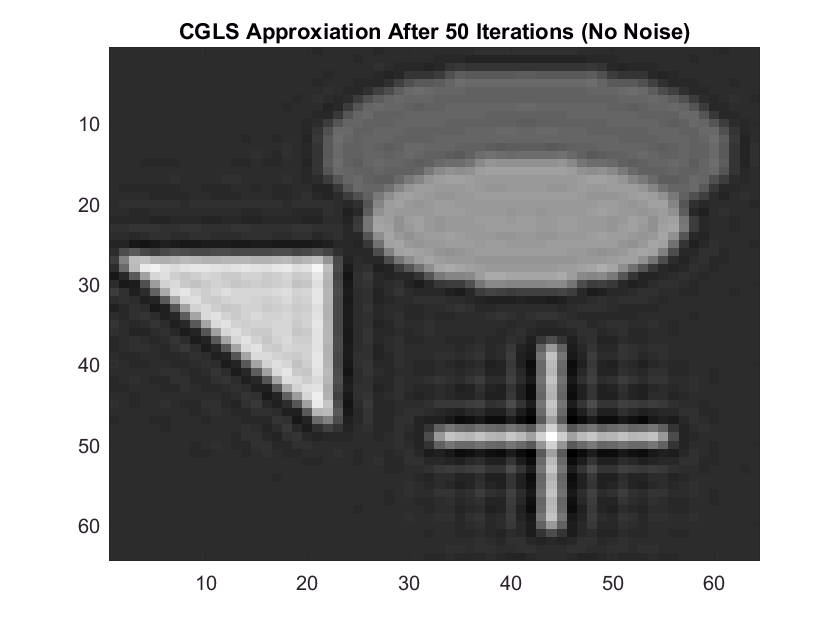

imagesc(X_50)
title('CGLS Approxiation After 50 Iterations (No Noise)')

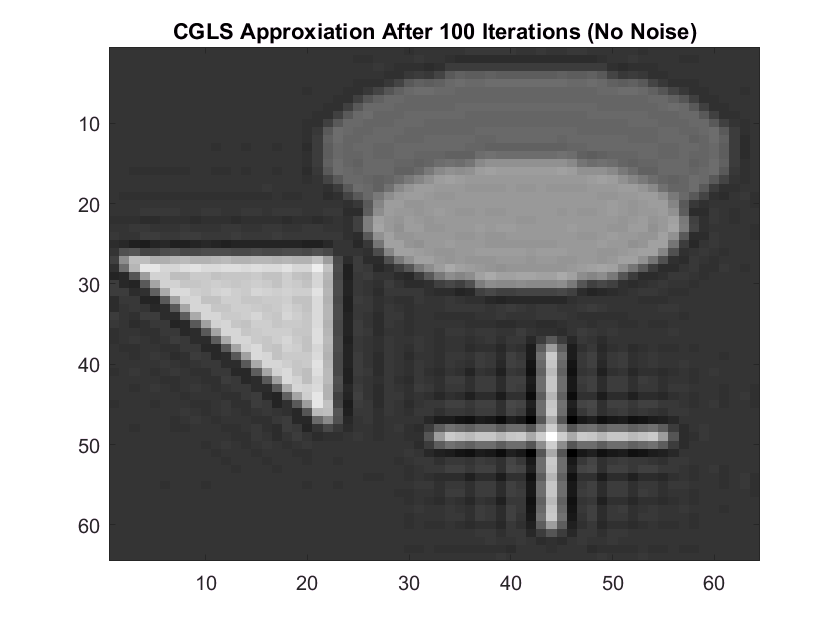

imagesc(X_100)
title('CGLS Approxiation After 100 Iterations (No Noise)')

%imagesc(X_1000)

## (c)

With added noise, taking the same approach as before and picking approximations out at random is not helpful. The approximations are likely to be unrecognizable. The quality of the reconstruction may actually deteriorate when the number of iterations is increased. If the noise is increased beyond what we use for the assignment the images become more unrecognizable and with less noise it may still be possible to recognize the original image after a large number of iterations. Still, it appears that a 'small' number of iterations does a better job in the presence of noise. For the noise level specified in the assignment, we can see how this might look using 1000 iterations:

noise = randn(length(y),1);
error = (0.1*norm(y))*noise/norm(noise); %Change 0.1 to other values to experiment with the noise level.
norm(error)/norm(y)

ans =           0.1


y_noisy = y + error;
n = 1000;
tic
X_CGLS_noisy = cgls(y_noisy, G, n);
toc

Elapsed time is 4.235844 seconds.


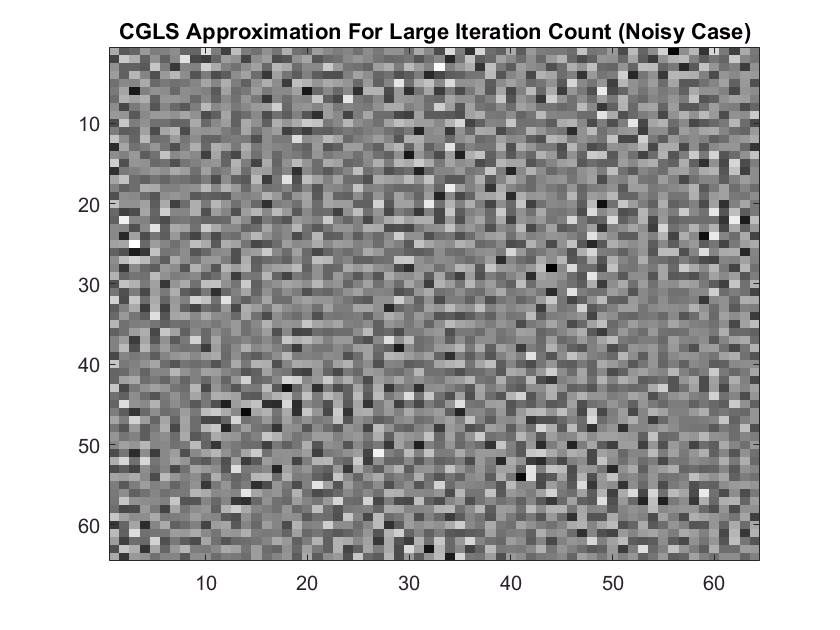


X_end_noisy = reshape(X_CGLS_noisy(:,end), N,N);
imagesc(X_end_noisy)
title('CGLS Approximation For Large Iteration Count (Noisy Case)')

The results are better if just using approximations from earlier iterations:

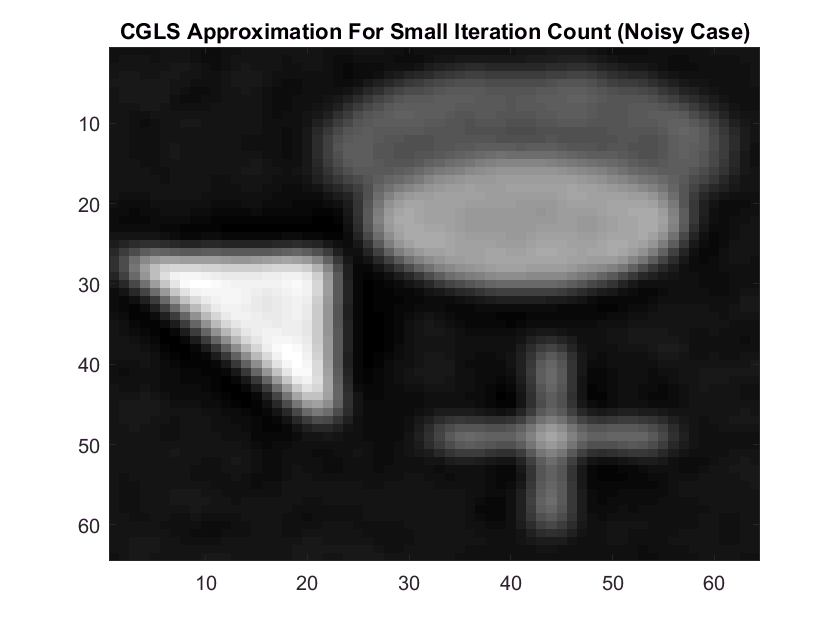

imagesc(reshape(X_CGLS_noisy(:,3), N,N))
title('CGLS Approximation For Small Iteration Count (Noisy Case)')

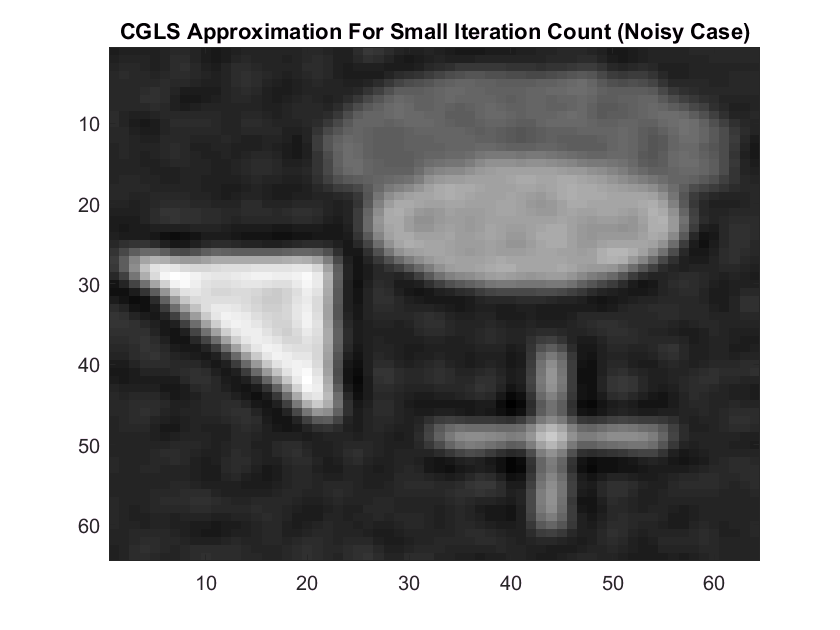

imagesc(reshape(X_CGLS_noisy(:,5), N,N))
title('CGLS Approximation For Small Iteration Count (Noisy Case)')

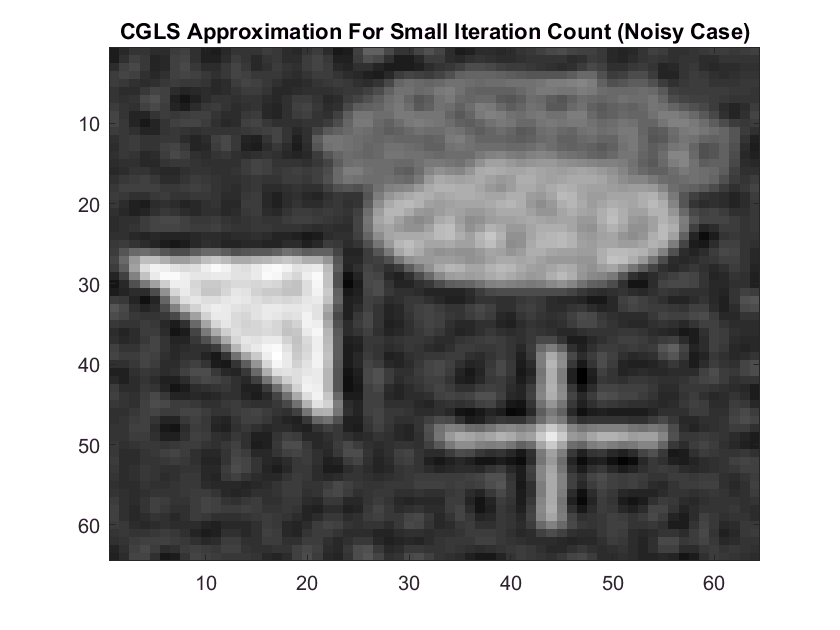

imagesc(reshape(X_CGLS_noisy(:,10), N,N))
title('CGLS Approximation For Small Iteration Count (Noisy Case)')

## (d)

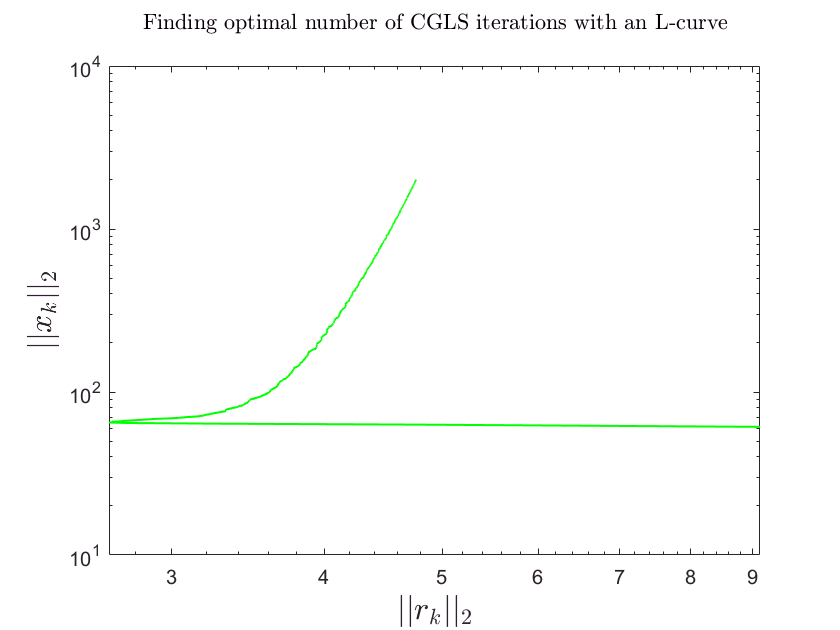


residual_norms = zeros(1,n+2);
x_norms = zeros(1,n+2);

for ii = 1:n
    
    residual_norms(ii) = norm(G*X_CGLS_noisy(:,ii) - y);
    x_norms(ii) = norm(X_CGLS_noisy(:,ii));
    
end

loglog(residual_norms, x_norms, 'g', 'linewidth', 1)
xlabel('$$||r_k||_2$$','FontSize',16,'interpreter','latex');
ylabel('$$||x_{k}||_2$$','FontSize',16,'interpreter','latex');
title({'' 'Finding optimal number of CGLS iterations with an L-curve' ''},'Interpreter','latex')

The corner of the L-curve corresponds roughly to where the norm of the residual is about 2.6091. This occurs in the eighth position of our residual norm vector, corresponding to $||Gx^{(7)} - y||_2$ from the seventh iteration. The reconstruction for this iteration looks like:

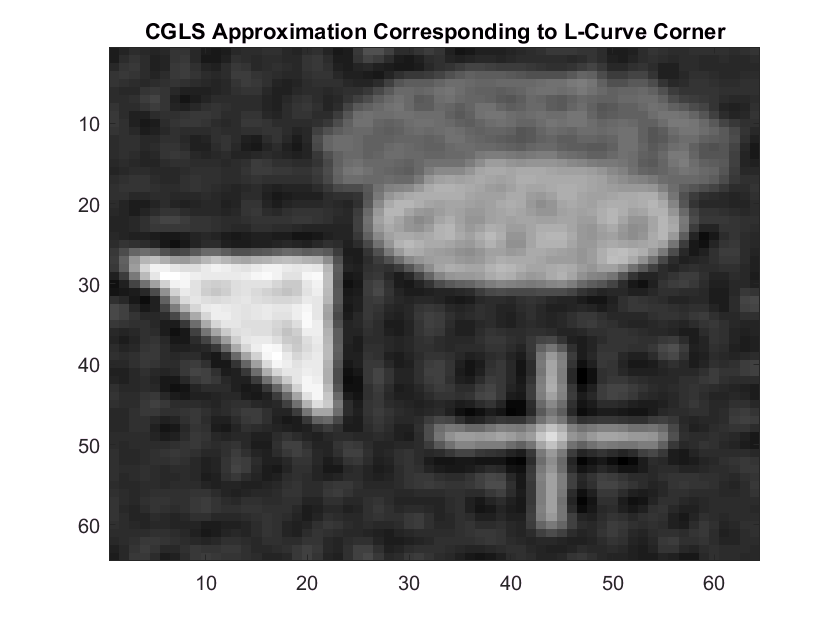

imagesc(reshape(X_CGLS_noisy(:,8),N,N))
title('CGLS Approximation Corresponding to L-Curve Corner')

 I will define "the solution that is closest to $x_{true}$" as the iterate solution that minimizes the 2-norm of the difference between the approximation $x^{(k)}$ and $x_{true}$. This happened (it could maybe change due to the noise) at the sixth iteration. This is almost the same as what a visual inspection of the L-curve gave and it is possible that this is actually where the corner of the L-curve was and I did not see it quite accurately enough. In any case it's about the same quality:

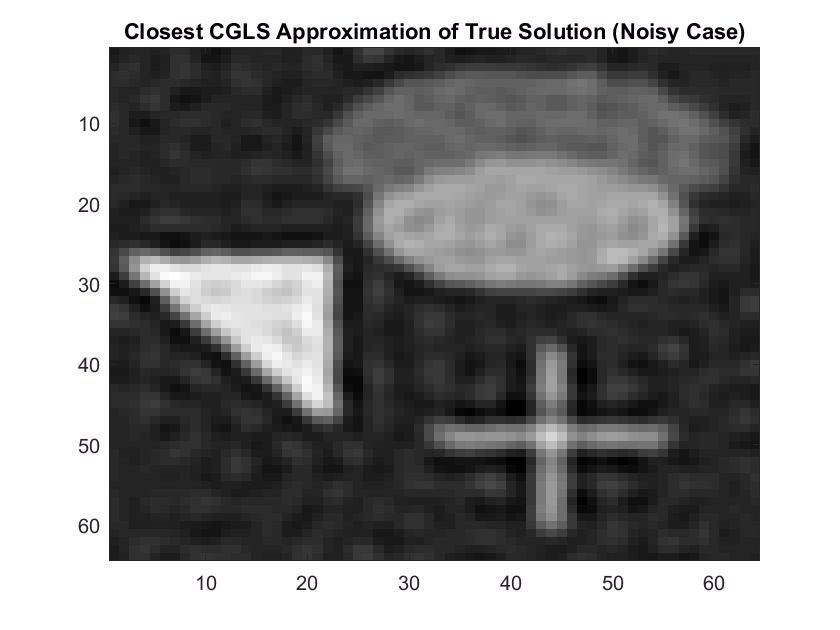

x_errors = zeros(1,1002);
for kk = 1:1002
x_errors(kk) = norm(X_CGLS_noisy(:,kk) - x);
end
[minimum_error,minimum_error_index] = min(x_errors);
imagesc(reshape(X_CGLS_noisy(:,minimum_error_index),N,N))
title('Closest CGLS Approximation of True Solution (Noisy Case)')

Increasing the amount of blur changes the anwer to part (b) slightly. The quality of reconstruction still appears to reach an upper bound that does not fully recover $x_{true}$ however that upper bound on quality takes longer to attain. The quality after about 10 iterations is noticeably worse than after about 100. Even after about 1000 iterations, the reconstruction still has defects that were not present at low levels of iteration with lower blur.

Increasing noise alone while keeping the rest of our conditions standard with respect to the problem tends to give an optimal iteration number lower than with our original noise level. Depending on the level of noise used, the resulting L-curve may or may not be an L at all. In the cases that I could still find a corner, it matched up well with the result for the solution closest to $x_{true}$ as this was defined above (yes this really was the case when manually checking the L-Curve and elements of the approximation error vector). But then increasing the relative noise level by two orders of magnitude or more makes the reconstruction process essentially useless - you can only decide whether the reconstruction will be very pixelated or very solid gray. 

Similarly, increasing both blur and noise makes the reconstruction process mostly impossible. It was still possible at times to find an L-curve with a corner and this corner still matched up with the closest approximation of $x_{true}$, even if this optimal approximation was unrecognizable. 

To make this live script more concise, these experiments were conducted separately in the file "Problem1d_Experiments.m".

## Problem 2

Gradient descent reconstructs the solution of the blur problem with similar quality compared to what we saw for CGLS for the case with no noise. Using tic and toc, Matlab times gradient descent much slower than CGLS. Here we show the result after 10 iterations and 100 iterations.

% Computations that will be used throughout gradient descent can be found once rather than recomputing in the loop.
% It doesn't seem possible to perform gradient descent without doing this at least once?
GTG = G'*G;
GTy = G'*y;

X = zeros(length(x),1);

% Set the stopping criterion to be the case that the approximations are no longer changing by much.
change = 1;
tolerance = 10^-2;
iteration = 1;

tic
while change > tolerance
    
    p_k = GTG*X(:,iteration) - GTy;
    alpha_k = (norm(p_k))^2/(norm(G*p_k))^2;
    X(:,iteration+1) = X(:,iteration) - alpha_k*p_k;
    change = norm(X(:,iteration+1) - X(:,iteration));
    iteration = iteration + 1;
    
end
toc

Elapsed time is 0.592333 seconds.


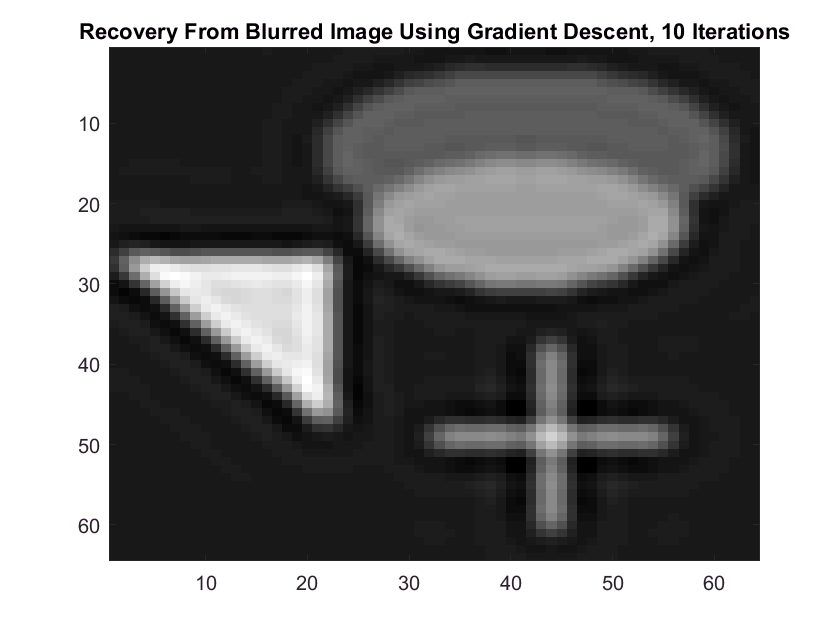


imagesc(reshape(X(:,11),N,N))
title('Recovery From Blurred Image Using Gradient Descent, 10 Iterations')


imagesc(reshape(X(:,101),N,N))

Index exceeds matrix dimensions.

title('Recovery From Blurred Image Using Gradient Descent, 101 Iterations')

When adding noise to blurred image, we see something similar to before - early iterations look better than the approximations for larger iterations. Gradient descent still runs quickly compared to CGLS here.

noise = randn(length(y),1);
error = (0.1*norm(y))*noise/norm(noise); %Change 0.1 to other values to experiment with the noise level.

y_noise  = y + error;

GTG = G'*G;
GTy = G'*y_noise;

X = zeros(length(x),1);

change = 1;
tolerance = 10^-2;
iteration = 1;

tic
while change > tolerance
    
    p_k = GTG*X(:,iteration) - GTy;
    alpha_k = (norm(p_k))^2/(norm(G*p_k))^2;
    X(:,iteration+1) = X(:,iteration) - alpha_k*p_k;
    change = norm(X(:,iteration+1) - X(:,iteration));
    iteration = iteration + 1;
    
end
toc

imagesc(reshape(X(:,6),N,N))
title('Gradient Descent Reconstruction with Noise, 5 iterations')

imagesc(reshape(X(:,11),N,N))
title('Gradient Descent Reconstruction with Noise, 10 iterations')

imagesc(reshape(X(:,101),N,N))
title('Gradient Descent Reconstruction with Noise, 100 iterations')

residual_norms = zeros(1,iteration);
x_norms = zeros(1,iteration);

for ii = 1:iteration
    
    residual_norms(ii) = norm(G*X(:,ii) - y);
    x_norms(ii) = norm(X(:,ii));
    
end

loglog(residual_norms, x_norms, 'g', 'linewidth', 1)
xlabel('$$||r_k||_2$$','FontSize',16,'interpreter','latex');
ylabel('$$||x_{k}||_2$$','FontSize',16,'interpreter','latex');
title({'' 'Finding optimal number of Gradient Descent iterations with an L-curve' ''},'Interpreter','latex')
x_errors = zeros(1,iteration);
for kk = 1:iteration
x_errors(kk) = norm(X(:,kk) - x);
end
[minimum_error,minimum_error_index] = min(x_errors);
imagesc(reshape(X_CGLS_noisy(:,minimum_error_index),N,N))

By inspecting an L-Curve and also finding the closest approximation of the true solution, we see that the L-Curve can work for finding the optimal iteration count for Gradient Descent as well, even if it seems that the optimal iteration count is different than for CGLS.

Finally, we use Gradient Descent on the Shaw test problem. Decreasing the tolerance does not hurt runtime for this case and helps provide a more accurate solution.

[G,y,x] = shaw(64);

GTG = G'*G;
GTy = G'*y;

X = zeros(length(x),1);

% Set the stopping criterion to be the case that the approximations are no longer changing by much.
change = 1;
tolerance = 10^-4;
iteration = 1;

while change > tolerance
    
    p_k = GTG*X(:,iteration) - GTy;
    alpha_k = (norm(p_k))^2/(norm(G*p_k))^2;
    X(:,iteration+1) = X(:,iteration) - alpha_k*p_k;
    change = norm(X(:,iteration+1) - X(:,iteration));
    iteration = iteration + 1;
    
end

iteration

plot2 = plot(1:64, X(:,end), 1:64, x, 'linewidth', 1);
title({'' 'True Solution of Shaw Test Problem and' 'Gradient Descent Approximation'})
xlabel('index')
ylabel('$$x_{true}, x_{GSELS}$$', 'interpreter', 'latex')
names = {'x_{GSELS}', 'x_{true}'};
legend(plot2, names, 'location', 'northwest')

Repeating Gradient Descent on the Shaw Test problem with some noise increases the iterations needed to recreate the same quality as without noise but can still achieve a reasonable approximation unless the noise level is prohibitively high. 

y_noise = y + 10^-2*randn(length(y),1);

GTG = G'*G;
GTy = G'*y_noise;

X = zeros(length(x),1);

% Set the stopping criterion to be the case that the approximations are no longer changing by much.
change = 1;
tolerance = 10^-4;
iteration = 1;

while change > tolerance
    
    p_k = GTG*X(:,iteration) - GTy;
    alpha_k = (norm(p_k))^2/(norm(G*p_k))^2;
    X(:,iteration+1) = X(:,iteration) - alpha_k*p_k;
    change = norm(X(:,iteration+1) - X(:,iteration));
    iteration = iteration + 1;
    
end

iteration

plot2 = plot(1:64, X(:,end), 1:64, x, 'linewidth', 1);
title({'' 'True Solution of Shaw Test Problem and' 'Gradient Descent Approximation (Noisy Case)'})
xlabel('index')
ylabel('$$x_{true}, x_{GSELS}$$', 'interpreter', 'latex')
names = {'x_{GSELS}', 'x_{true}'};
legend(plot2, names, 'location', 'northwest')

## Bonus:

I am feeling deterministic right now. 